# PARAFAC tutorial

Notice: This is a tutorial on how to PARAFAC with the toolbox. For an in-depth discussion on valid models, please refer to [Murphy et al. (2013)](https://pubs.rsc.org/en/content/articlehtml/2013/ay/c3ay41160e). The models produced in this tutorial might not satisfy all criteria of validity and are simply intended to demonstrate procedures and toolbox functionality.

## Toolbox setup and initiation

clearvars
close all force
cd(fileparts(matlab.desktop.editor.getActiveFilename))
tbx=drEEMtoolbox;
load("tutorial_01_processed.mat")

## Hold up! How does your data look?

Ready, right? Not quite! There's a simple rule that applies in computer science: [GIGO, or garbage in, garbage out](https://en.wikipedia.org/wiki/Garbage_in,_garbage_out). We can't expect a representation of our data to look reasonable if the algorithm is fed unreasonable data. We need to take a look at the data first if we have not done so already.

tbx.viewabsorbance(samples)
tbx.vieweems(samples)

Also, is the dataset ready for PARAFAC?

disp(samples.status)

For example, the fluoresccence signals should be calibrated in some way (the toolbox supports Raman Units). Scatter should be removed. Good news is that the toolbox actually checks for you!

After you browsed through the data above and agree that the samples look reasonable, we can proceed to fit the first models.

## Preliminary test models & dataset refinement

samples=tbx.fitparafac(samples,f=2:7,convergence=1e-4,starts=2);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6  7]
Number of random starts:         2
Convergence criterion:           0.0001
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.749
-----
  
# 001 done | #iter: 32   | core%: 96 | time: 00:00:00 | it/sec: 41
# 002 done | #iter: 23   | core%: 95 | time: 00:00:00 | it/sec: 29
# 003 done | #iter: 32   | core%: 22 | time: 00:00:00 | it/sec: 41
# 004 done | #iter: 26   | core%: 26 | time: 00:00:00 | it/sec: 33
# 005 done | #iter: 117  | core%: 4 | time: 00:00:01 | it/sec: 113
# 006 done | #iter: 103  | core%: 7 | time: 00:00:01 | it/sec: 103
# 007 done | #iter: 208  | core%: 21 | time: 00:00:01 | it/sec: 189
# 008 done | #iter: 366  | core%: 12 | time: 00:00:01 | it/sec: 207
# 009 done | #iter: 72   | core%: 0 | time: 00:00:01 | it

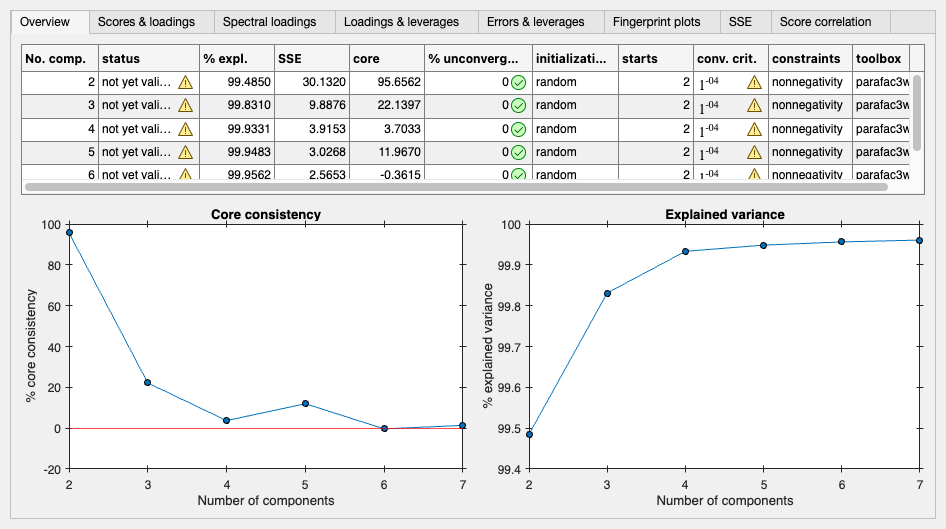

tbx.viewmodels(samples)

samples=tbx.addcomment(samples,"first outliertest. Seems quite ok. Need to lower convergence option. 7 components are likely too much.");

You can see that the first step was to fit lots of components with few starts to each and use a high convergence criterion. This used to be called "outliertest".

The conclusion from these models are that the data seems to produce reasonable PARAFAC models. Let's reduce the convergence criterion and use a few more models ("starts") to get a more firm idea.

See how I left myself a comment in the dataset? This way, you can retrace your steps and document your decision making process.

samples=tbx.fitparafac(samples,f=2:6,convergence=1e-6,starts=4);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.749
-----
  
# 001 done | #iter: 126  | core%: 99 | time: 00:00:00 | it/sec: 203
# 002 done | #iter: 126  | core%: 99 | time: 00:00:00 | it/sec: 176
# 003 done | #iter: 126  | core%: 99 | time: 00:00:00 | it/sec: 162
# 004 done | #iter: 126  | core%: 99 | time: 00:00:00 | it/sec: 179
# 005 done | #iter: 161  | core%: 19 | time: 00:00:00 | it/sec: 175
# 006 done | #iter: 306  | core%: 35 | time: 00:00:01 | it/sec: 231
# 007 done | #iter: 196  | core%: 44 | time: 00:00:01 | it/sec: 194
# 008 done | #iter: 268  | core%: 35 | time: 00:00:01 | it/sec: 233
# 009 done | #iter: 1283 | core%: 7 | time: 00:00:03 | 

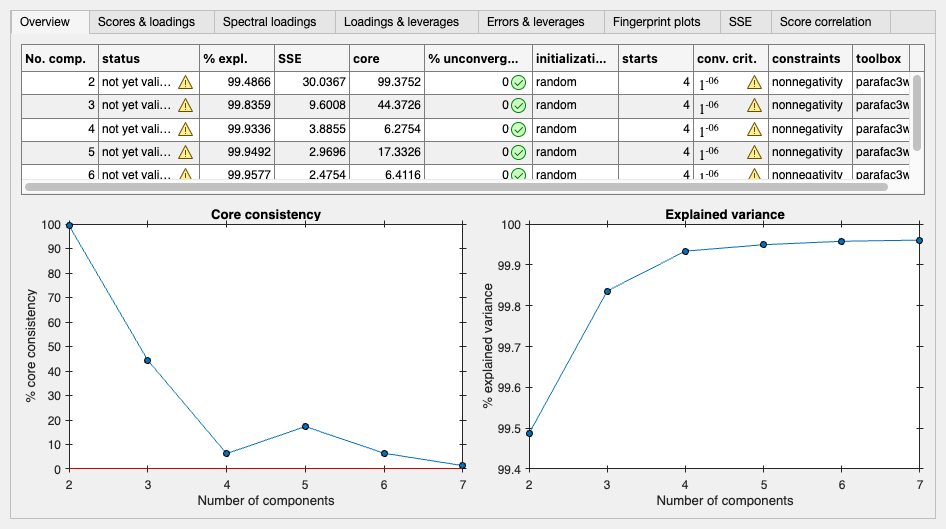

tbx.viewmodels(samples)

samples=tbx.addcomment(samples,"Very high correlation between scores. Trying to scale the samples.");

At this point, I can see that the correlation between scores (Tab "Score correlation") is high for many models and components. I would like to see if scaling of the samples changes this.

samples=tbx.scalesamples(samples,2);
samples=tbx.addcomment(samples,"Scale with the square root (2) of the standard deviation (Pareto scaling)");
samples=tbx.fitparafac(samples,f=2:6,convergence=1e-6,starts=4);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.749
-----
  
# 001 done | #iter: 146  | core%: 99 | time: 00:00:00 | it/sec: 197
# 002 done | #iter: 146  | core%: 99 | time: 00:00:00 | it/sec: 189
# 003 done | #iter: 146  | core%: 99 | time: 00:00:00 | it/sec: 203
# 004 done | #iter: 30   | core%: 98 | time: 00:00:00 | it/sec: 48
# 005 done | #iter: 353  | core%: 49 | time: 00:00:01 | it/sec: 309
# 006 done | #iter: 369  | core%: 49 | time: 00:00:01 | it/sec: 326
# 007 done | #iter: 208  | core%: 49 | time: 00:00:00 | it/sec: 227
# 008 done | #iter: 356  | core%: 49 | time: 00:00:01 | it/sec: 320
# 009 done | #iter: 2326 | core%: 8 | time: 00:00:04 | i

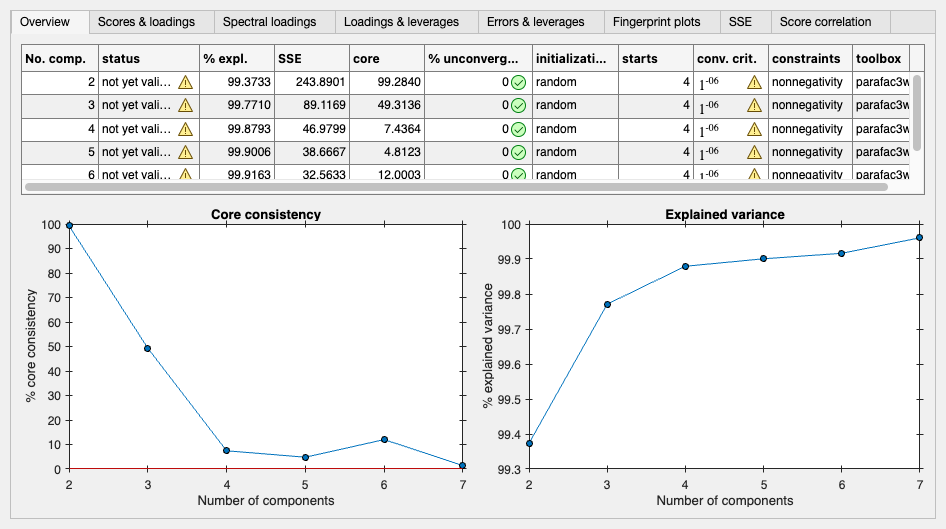

tbx.viewmodels(samples)

samples=tbx.addcomment(samples,"Still very correlated scores. There's a noisy component. Perhaps delete some of the noisy short ex-wavelengths?");

We use `scalesamples` to perform the scaling. `Scalesamples` replaces the `normeem` function of earlier toolbox versions. If you want the equivalent output to the old `normeem`, `samples=tbx.scalesamples(samples,1)`; would do the trick. The higher the second input to `scalesamples`, the more gentle the scaling will be (eventually making no practical difference). Read more [here](matlab:open('scalesamples.html')).

samples=tbx.subdataset(samples,outEx=samples.Ex<255);

A call to subdataset with pre-existing models results in their deletion.
A call to subdataset with pre-existing models results in their deletion.


samples=tbx.fitparafac(samples,f=2:6,convergence=1e-6,starts=4);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.956
-----
  
# 001 done | #iter: 132  | core%: 100 | time: 00:00:00 | it/sec: 237
# 002 done | #iter: 126  | core%: 100 | time: 00:00:00 | it/sec: 198
# 003 done | #iter: 132  | core%: 100 | time: 00:00:00 | it/sec: 209
# 004 done | #iter: 112  | core%: 100 | time: 00:00:00 | it/sec: 173
# 005 done | #iter: 287  | core%: 51 | time: 00:00:01 | it/sec: 282
# 006 done | #iter: 322  | core%: 51 | time: 00:00:00 | it/sec: 323
# 007 done | #iter: 343  | core%: 51 | time: 00:00:01 | it/sec: 332
# 008 done | #iter: 333  | core%: 51 | time: 00:00:00 | it/sec: 358
# 009 done | #iter: 1966 | core%: 7 | time: 00:00:0

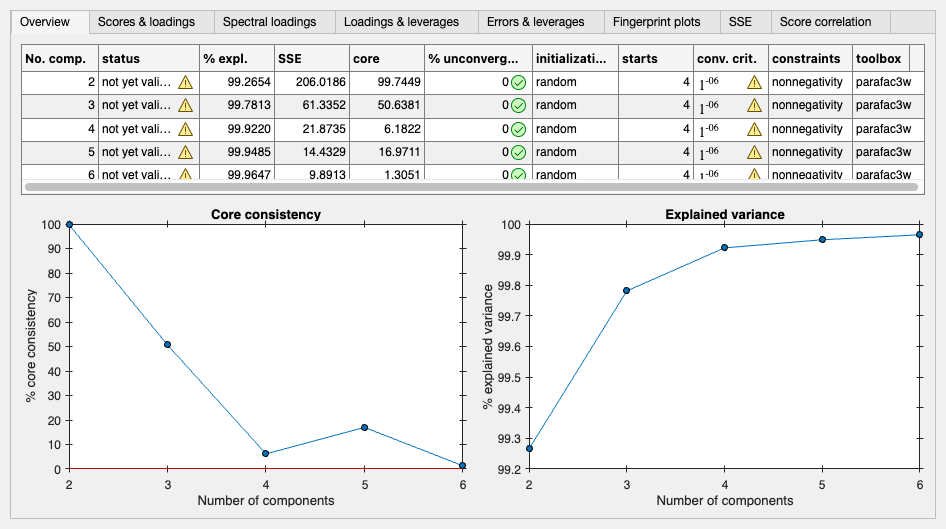

tbx.viewmodels(samples)

samples=tbx.addcomment(samples,"The component spectra look smooth but have some features we don't generally like much.");

samples =   drEEMdataset with properties:

            history: [17×1 drEEMhistory]
                  X: [32×182×40 double]
                abs: [32×73 double]
        suppSpectra: []
           filelist: {32×1 cell}
                  i: [32×1 double]
                 Ex: [40×1 double]
                 Em: [182×1 double]
                nEx: 40
                nEm: 182
            absWave: [73×1 double]
    suppSpectraAxis: [0×1 double]
            nSample: 32
             models: [6×1 drEEMmodel]
           metadata: [32×15 table]
    opticalMetadata: [0×0 table]
              split: [0×0 drEEMdataset]
             status: [1×1 drEEMstatus]
           userdata: []
     instrumentInfo: [0×0 struct]
    measurementInfo: [0×0 struct]
        toolboxdata: [1×1 struct]


samples=tbx.addcomment(samples,"Samples 2-4 have a high modeling error and leverage. Outliers?");

My comments above summarize my observations. Components generally look fine but don't adhere to properties typically observed with pure fluorophores. From a diagnostics perspective, I can see that some samples (2-4) have high leverage and a high error when modelling with few components. We can try to remove them, though they don't look like outliers (use `vieweems` to inspect them).

samples=tbx.subdataset(samples,outSample=ismember(samples.i,2:4));
samples=tbx.fitparafac(samples,f=2:7,convergence=1e-6,starts=4);

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6  7]
Number of random starts:         4
Convergence criterion:           1e-06
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.956
-----
  
# 001 done | #iter: 251  | core%: 60 | time: 00:00:00 | it/sec: 347
# 002 done | #iter: 249  | core%: 60 | time: 00:00:00 | it/sec: 350
# 003 done | #iter: 231  | core%: 60 | time: 00:00:00 | it/sec: 312
# 004 done | #iter: 216  | core%: 61 | time: 00:00:00 | it/sec: 342
# 005 done | #iter: 272  | core%: 39 | time: 00:00:00 | it/sec: 311
# 006 done | #iter: 312  | core%: 39 | time: 00:00:00 | it/sec: 348
# 007 done | #iter: 327  | core%: 39 | time: 00:00:00 | it/sec: 339
# 008 done | #iter: 327  | core%: 38 | time: 00:00:00 | it/sec: 354
# 009 done | #iter: 709  | core%: 15 | time: 00:00:0

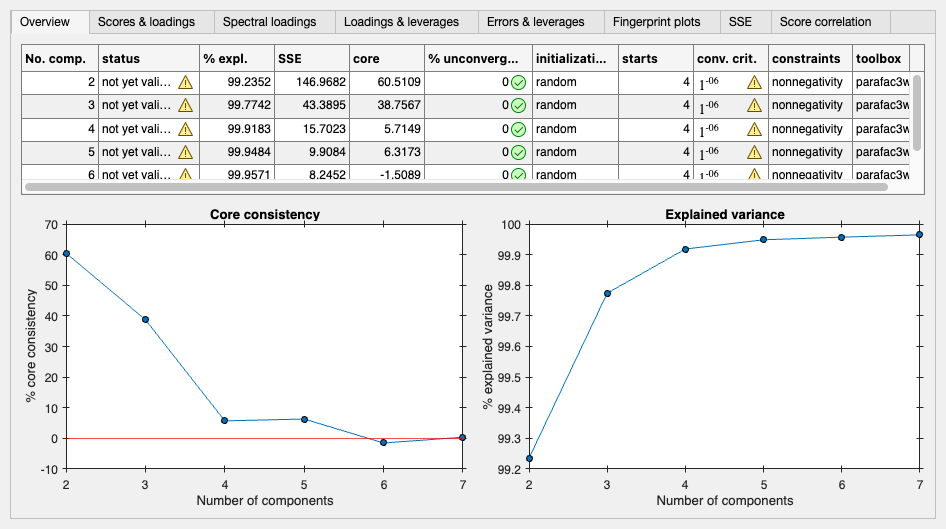

tbx.viewmodels(samples)

samples=tbx.addcomment(samples,"It does not look like that made a difference.");

We use [`subdataset`](matlab:open('subdataset.html')) and look for for samples with the identifier 2 to 4 ("`.i`"), remove them and run the models again. At this stage, if we can't improve the model much more, it would be a good idea to run the analysis again, with a low convergence criterion and many tries ("starts"). If you take a close look at the Overview tab's table, you might noticec that some models did not converge due to hitting the maximum number of iterations permitted (3000 by default). We can increase this number to avoid obtaining less models than we would wish. This might take a while...

samples=tbx.fitparafac(samples, ...

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [2  3  4  5  6  7]
Number of random starts:         50
Convergence criterion:           1e-08
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.956
-----
  
# 001 done | #iter: 240  | core%: 61 | time: 00:00:00 | it/sec: 285
# 002 done | #iter: 205  | core%: 61 | time: 00:00:00 | it/sec: 272
# 003 done | #iter: 244  | core%: 61 | time: 00:00:00 | it/sec: 328
# 004 done | #iter: 287  | core%: 61 | time: 00:00:00 | it/sec: 337
# 005 done | #iter: 210  | core%: 61 | time: 00:00:00 | it/sec: 278
# 006 done | #iter: 275  | core%: 61 | time: 00:00:00 | it/sec: 318
# 007 done | #iter: 258  | core%: 61 | time: 00:00:00 | it/sec: 298
# 008 done | #iter: 265  | core%: 61 | time: 00:00:00 | it/sec: 327
# 009 done | #iter: 275  | core%: 61 | time: 00:00:

    f=2:7, ...
    convergence=1e-8, ...
    starts=50, ...
    maxIteration=5000);
tbx.viewmodels(samples)

At this point, it's time to really inspect the residuals since we haven't done that at all. This can be done at any point, but it's not too bad to wait until we're quite confident in the model. You might really want to do this earlier if you don't like the models at all. The residuals might give clues as to where the data is not well explained or why the model looks strange to begin with. 

In short, we need to compare the raw fluorescence ***d***ata with the ***m***odel and the resulting ***r***esiduals. We can do this with [`viewdmr`](matlab:open('viedmr.html')) (but also [`vieweems`](matlab:open('vieweems.html'))). Simply chose the model you are most convinced of and look at the residuals

tbx.viewdmr(samples)

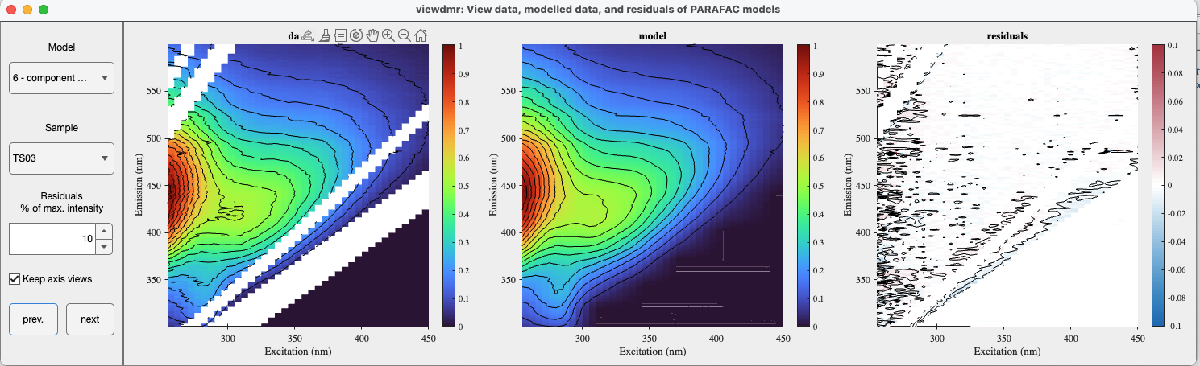

In the example above, the residuals reveal that some of the scatter was not cut. Particularly Rayleigh 2nd order (above and below), but also 1st order (above). Perhaps also some of the 1st order Raman (above and below), but to a lesser extent. Since the scatter removal was quite modest to begin with here, it might pay off to redo this and see if it helps with the loadings. Why?

***Scatter violates the model assumptions***

Non-trilinear data in your EEMs can really throw a wrench in the PARAFAC engine. There's really no telling what it'll do and it's difficult to diagnose. But it's the analyst's job to spot and attempt to fix it.

newSamples=samples;
tbx.viewscatter(newSamples)

viewscatter remembers the settings, so you don't start from scratch. You can just refine the settings and save them again to the workspace. I chose some settings and saved them to the workspace, then to the disk. Let's load them and apply them:

load("scatterSettings_refined.mat")
newSamples=tbx.handlescatter(newSamples,scatteroptions);

With that done, it's time to repeat the PARAFAC runs and see if it changed anything. We'll go straight to the `viewdmr` app, but you might also want to inspect the model with `viewmodels`.

newSamples=tbx.fitparafac(newSamples, ...
    f=2:7, ...
    convergence=1e-8, ...
    starts=50, ...
    maxIteration=5000);
%tbx.viewmodels(newSamples)
tbx.viewdmr(newSamples)

A this stage, the residuals look very random for most of these samples. A quick look at the models actually also reveals that the loadings improved for the excitation, but not for the emission.

tbx.viewmodels(newSamples)

Good and bad news, let's attept a model validation.

## Splitvalidation

newSamples=tbx.splitdataset(newSamples);

The default call to splitdataset performs a split into two datasets via an alternating assignment into split 1 or two. Here, we have very view samples and assigning the splits in this way also doesn't bias our split datasets in any way. However, this might not be the case in your dataset. 

***The validation is your safety check and you should perform it in a way that critically inspects your analysis. Have a look at the ***[***documentation***](matlab:open('splitdataset.html'))*** here.***

Next, we use the same function from before, but by specifiying `mode='split'`. This way, the function looks only at the split datasets, not the overall, original dataset. Though those models are still saved in the dataset as well.

newSamples=tbx.fitparafac(newSamples, ...

Existing parallel pool of 8 workers found and used...
  
-----
PARAFAC engine:                  parafac3w
Parallelization:                 true
Models with components:          [3  4  5  6]
Number of random starts:         50
Convergence criterion:           1e-08
Maximum number of iterations:    3000
Constraint:                      nonnegativity
% missing numbers:               13.956
-----
  
# 001 done | #iter: 776  | core%: 36 | time: 00:00:00 | it/sec: 804
# 002 done | #iter: 385  | core%: 36 | time: 00:00:00 | it/sec: 649
# 003 done | #iter: 711  | core%: 36 | time: 00:00:00 | it/sec: 810
# 004 done | #iter: 761  | core%: 36 | time: 00:00:00 | it/sec: 852
# 005 done | #iter: 868  | core%: 36 | time: 00:00:01 | it/sec: 808
# 006 done | #iter: 691  | core%: 36 | time: 00:00:00 | it/sec: 754
# 007 done | #iter: 726  | core%: 36 | time: 00:00:00 | it/sec: 803
# 008 done | #iter: 812  | core%: 36 | time: 00:00:01 | it/sec: 746
# 009 done | #iter: 700  | core%: 36 | time: 00:00:00 | i

    mode='split', ...
    f=4:6,convergence=1e-8, ...
    starts=50);

You can see from the final console output that the function also already performs spectral comparisons to let you know if the validation worked. The next call really only serves as visual output for ourselves.

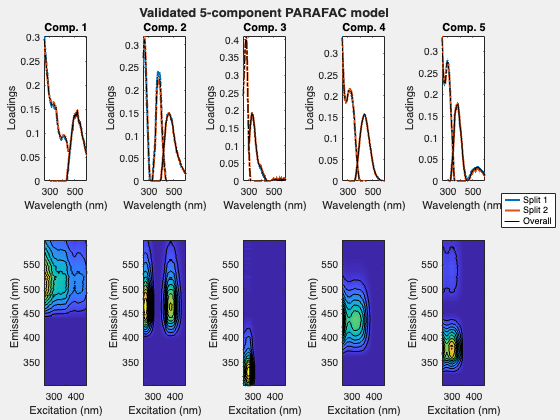

 
Overall Result= Validated for all comparisons


newSamples=tbx.splitvalidation(newSamples,5);

% newSamples=tbx.splitvalidation(newSamples,6); Run to inspect

So... the five component model validated, but the six-component model looks quite chaotic. It's not just a minor issue, but something to investigate in detail. How did that five component model look? Let's start with the residuals again and then look at the loadings.

tbx.viewdmr(newSamples)
tbx.viewmodels(newSamples)

There are some systematic residuals, particularly for the first couple of samples. The loadings are not ideal either: A double emission peak and excitation loadings that hit zeros. But here, we only have 29 samples that mostly came from an estuarine salinity gradient. Not the most variable, but for sure very autocorrolated dataset. So it's not a surprise that PARAFAC is finding this job difficult.

For the sake of this tutorial, we now move on to the next step.

## Data (model) export

Now that we've obtained a validated model, we could export it. You'd probably want to know how this model compares against what's out there. So let's get a .txt file that can be uploaded to OpenFluor.

tbx.export2openfluor(newSamples,5,'tutorial2openFluor.txt')

You might also want to export the results to a spreadsheet to analyze in Excel or other statistical programming environments.

tbx.exportresults(newSamples,5,'tutorialModelExport');